% clear

d = dipole('Tilt', 90);
% show(d)
[efield, az, el] = pattern(d, 75e6, 'Type', 'efield');

phi = az';
theta = (90-el);
MagE = efield';

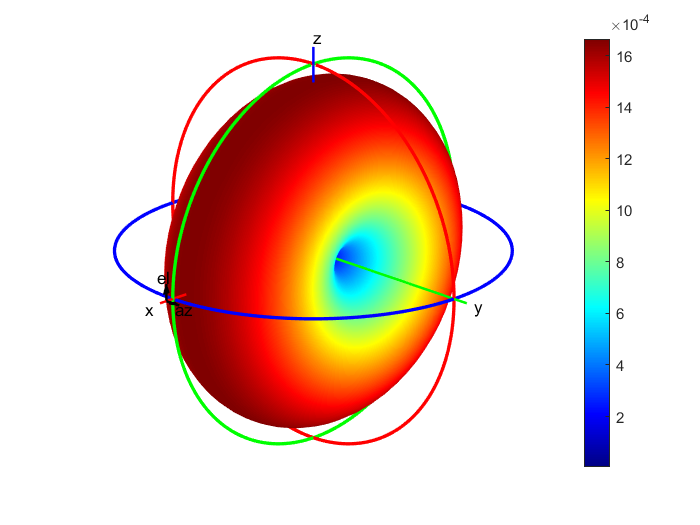

patternCustom(MagE, theta, phi)

h = helix;
[D,az,el] = pattern(h,2e9);
phi = az';
theta = (90-el);
MagE = D';

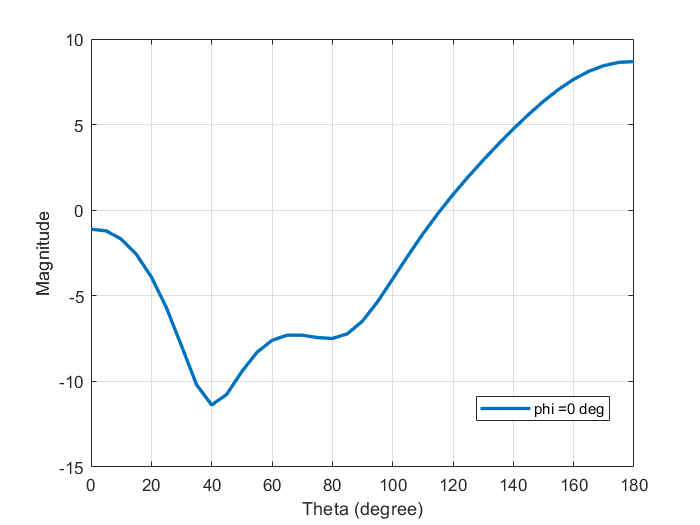

figure;
patternCustom(MagE,theta,phi,'CoordinateSystem','rectangular',...
    'Slice','phi','SliceValue',0);

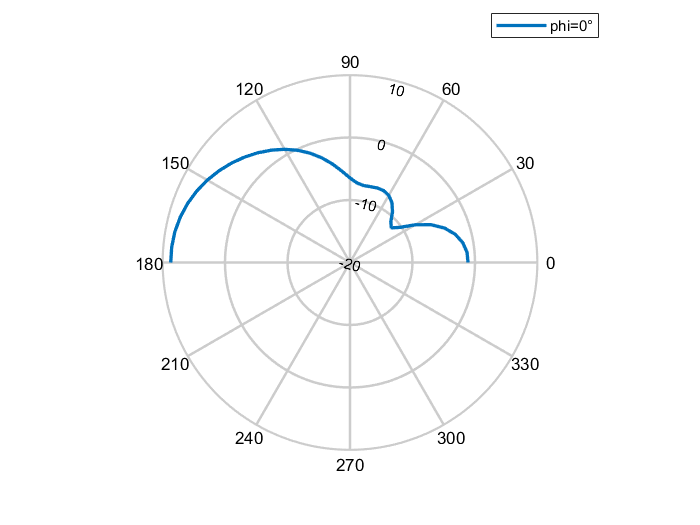

figure;
patternCustom(MagE, theta, phi,'CoordinateSystem','polar',...
    'Slice','phi','SliceValue',0);